# Step 2: data augmentation

In the previous step, we realized pixel-by-pixel labeling with the help of superpixelization and clustering method.

Now with image and its labels we can perform data augmentation. 

## 1) Configure the data path

Labeled image from previous step is stored in folder: /Train_example/labels.

These images are still pretty big even after scaling by 0.1 in previous step. We would like to crop the labeled images into 100*100 pixel images. Depending on the number of training images, we could define the number of cropped images. We recommend to crop approximately 5 images from one labeled image.

dataPath = fullfile(pwd, 'Train_example');

labelFolder = 'labels'; % this is the folder containing labeled images from previous step
resultFolder = 'Augmented_data'; % this is the target folder that augmented data will be stored
% again, in the target folder, we create separate folders to store images and labels
croppedImageFolder = 'images'; 
pixelLabelFolder = 'labels';

configure(pwd);
imageExtensions = {'.jpg'};
imageTags = {'resized'};
labelExtension = '.csv';

dataFilenameFormat = 'data%04d%s%s%s'; % e.g. data0001.jpg
croppedImageSize = 100;  % the cropped image dimension, default = 100 pixels

% the number of cropped image generated, should be adjust accordingly
numberOfDataPoints = 20;  

labelPath = fullfile(dataPath, labelFolder);
resultPath = fullfile(dataPath, resultFolder);
croppedImagePath = fullfile(resultPath,croppedImageFolder);
pixelLabelPath = fullfile(resultPath, pixelLabelFolder);

Folders are created for the cropped images and corresponding labels (if not exist).

if ~exist(resultPath, 'dir')
    mkdir(resultPath);
end

if ~exist(croppedImagePath, 'dir')
    mkdir(croppedImagePath);
end

if ~exist(pixelLabelPath, 'dir')
    mkdir(pixelLabelPath);
end

## 2) Generate data files

Now we need to create an image list from the folder: /Train_example/labels. And then we read the image file one by one.

imageList = {};

for iter = 1:length(imageExtensions)
    imageList = [imageList;...
        getAllFiles(labelPath, sprintf('*_%s%s',imageTags{iter},imageExtensions{iter}), 0)];
end

Then we start to generate data files.

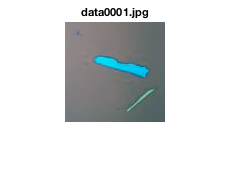

figure(1);clf(1);

figure(1);

for iter = 1:numberOfDataPoints
    % pick up one image randomly from the list
    numberOfImages = length(imageList);
    imageID = ceil(rand()*numberOfImages); % pick up one image randomly

    imageFilename = imageList{imageID};
    [path, name, ext] = fileparts(imageFilename);
    labelFilename = sprintf('%s%s',name(1:end-8), labelExtension);
    imageCropped = imread(fullfile(labelPath,imageFilename)); % read the image file
    label = csvread(fullfile(labelPath,labelFilename));

    % crop the image
    imageSize = size(imageCropped);
    bottomLeftCornerRange = imageSize(1:2)-croppedImageSize+1;
    bottomLeftCorner = ceil(rand([1,2]).*bottomLeftCornerRange);

    imageCropped = ...
        imageCropped(bottomLeftCorner(1):bottomLeftCorner(1)+croppedImageSize-1,...
        bottomLeftCorner(2):bottomLeftCorner(2)+croppedImageSize-1,:);

    labelCropped = ...
        label(bottomLeftCorner(1):bottomLeftCorner(1)+croppedImageSize-1,...
        bottomLeftCorner(2):bottomLeftCorner(2)+croppedImageSize-1);
    labelCropped = uint8(labelCropped);
    
    figure(1); 
    % normalize the image
    imageCropped = normalize(imageCropped);
    imshow(imageCropped); 
    title(sprintf(dataFilenameFormat,iter,'.jpg'));
    pause(0.1);
    
    % save the generated data
    tags = '_normalized';
    imwrite(imageCropped, fullfile(croppedImagePath,sprintf(dataFilenameFormat,iter,name,tags,'.jpg')));
    imwrite(label, fullfile(pixelLabelPath,sprintf(dataFilenameFormat,iter,name,tags,'.png')));

We also perform a number of transformations to the cropped image.    

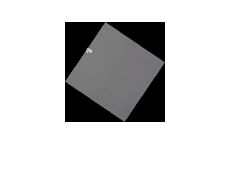

    % shear the image    
    % X direction
    tform = affine2d([1 0 0; rand() 1 0; 0 0 1]);
    warpImage = imresize(imwarp(imageCropped,tform), [croppedImageSize croppedImageSize]);
    warpLabel = imresize(imwarp(label,tform), [croppedImageSize croppedImageSize]);
    tags = sprintf('_shear1_%f',rand());
    figure(1);
    imshow(warpImage);
    pause(0.01);
    % save the generated data
    imwrite(warpImage, fullfile(croppedImagePath,sprintf(dataFilenameFormat,iter,name,tags,'.jpg')));
    imwrite(warpLabel, fullfile(pixelLabelPath,sprintf(dataFilenameFormat,iter,name,tags,'.png')));

 
    % Y direction shear
    tform = affine2d([1 rand() 0; 0 1 0; 0 0 1]);
    warpImage = imresize(imwarp(imageCropped,tform), [croppedImageSize croppedImageSize]);
    warpLabel = imresize(imwarp(label,tform), [croppedImageSize croppedImageSize]);
    tags = sprintf('_shear2_%f',rand());
    figure(1);
    imshow(warpImage);
    pause(0.01);
    % save the generated data
    imwrite(warpImage, fullfile(croppedImagePath,sprintf(dataFilenameFormat,iter,name,tags,'.jpg')));
    imwrite(warpLabel, fullfile(pixelLabelPath,sprintf(dataFilenameFormat,iter,name,tags,'.png')));
    
    %rotate image
    rotateAngle = rand()*360;
    rotateImage = imresize(imrotate(imageCropped, rotateAngle), [croppedImageSize croppedImageSize]);
    rotateLabel = imresize(imrotate(label, rotateAngle), [croppedImageSize croppedImageSize]);
    tags = sprintf('_rotate%f',rotateAngle);
    figure(1);
    imshow(rotateImage);
    pause(0.01);
    % save the generated data
    imwrite(warpImage, fullfile(croppedImagePath,sprintf(dataFilenameFormat,iter,name,tags,'.jpg')));
    imwrite(warpLabel, fullfile(pixelLabelPath,sprintf(dataFilenameFormat,iter,name,tags,'.png')));

end

Now the generated data will be stored at folder: /Train_example/Augmented_data.

We also include examples of generated data in the main directory /Augmented_data.